# Comparación resultados Teóricos y Simulados Escenario 10

## Resultados de simulación sin Obstaćulos


%Promedio PDR
%Filas Densidad de menos a mas, columnas Beconing 1,2,5 y 10 Hz

PDR_MEAN(1,:) = [[0.9619834710743801], [0.968038455051442], [0.9655369455760354], [0.9525308414831908]];

%Promedio CBR:
CBR_MEAN(1,:) = [[0.01466745074709929], [0.02945216170473459], [0.07348834441511165], [0.1457283478802252]];

%STD PDR:
PDR_STD(1,:) = [[0.009467717533861], [0.0], [0.0038187614588202027], [0.010057043048802923]];

%STD CBR:
CBR_STD(1,:) = [[0.0002324764983734277], [0.0004213189738697], [0.0011100330502306977], [0.0021587329963413627]];

## Resultados de modelo teórico

PDR_T = [0.9819 0.9775 0.9641 0.9419];
CBR_T = [0.0180 0.0215 0.0322 0.0499];
NAR_T = 1-(1-PDR_T).^5.4579;


## Resultados de simulación con obstáculos

% PDR Con obstáculos
PDR2_MEAN(1,:) =[[0.4072524877719683], [0.4076720357564513], [0.405152639568224], [0.39771420138303254]];

% STD PDR:
PDR2_STD(1,:) = [[0.0033682234008854737], [0.0017796641965173127], [0.0034116135246280662], [0.00488385668366826]];

CBR2_MEAN(1,:) = [[0.006037878647682177], [0.012083325128342643], [0.030124227260093752], [0.059627479482255746]];

%STD CBR:
CBR2_STD(1,:) =[[0.00218361270867478], [0.0043693478416257855], [0.010861572934337614], [0.021291627024541765]];


## Obtención de NAR

Sc1 = [ PDR_T(1,:) ; PDR_MEAN(1,:) ; PDR2_MEAN(1,:)];

z=5.4579;
Sc1_nar = 1-(1-Sc1).^5.4579;

Sc1_c = [ CBR_T(1,:) ; CBR_MEAN(1,:) ; CBR2_MEAN(1,:)];

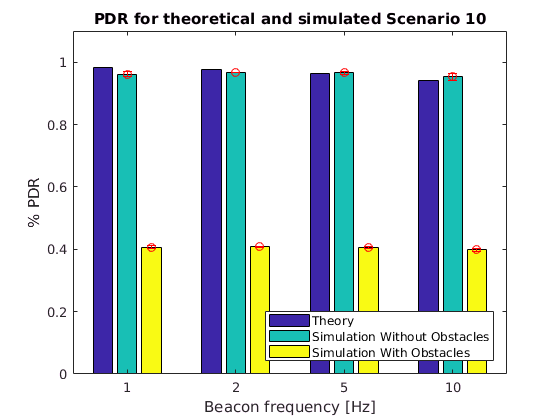

figure (1)

bar(Sc1','DisplayName','PDR_MEAN');
hold on

title('PDR for theoretical and simulated Scenario 10');
xlabel('Beacon frequency [Hz]');
ylabel('% PDR');

x=[1 2 3 4];
%x2=[];
%x2(:,1)=x-0.27;
%x2(:,2)=x-0.1;
%x2(:,3)=x+0.1;
%x2(:,4)=x+0.27;
x2 = x + 0.22;
errorbar(x,PDR_MEAN(1,:),PDR_STD(1,:),'ro');
hold on
errorbar(x2,PDR2_MEAN(1,:),PDR2_STD(1,:),'ro');
legend('Theory','Simulation Without Obstacles','Simulation With Obstacles','Location','SouthEast');
ylim([0, 1.1])
xticklabels([1 2 5 10])
hold off

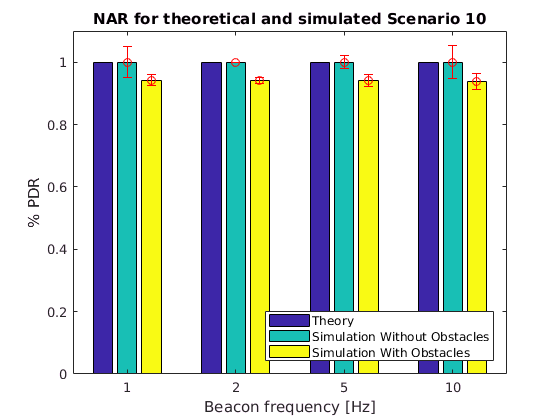

figure (2)

bar(Sc1_nar','DisplayName','PDR_MEAN');
hold on

title('NAR for theoretical and simulated Scenario 10');
xlabel('Beacon frequency [Hz]');
ylabel('NAR');

x=[1 2 3 4];
x2 = x + 0.22;
errorbar(x,(1-(1-PDR_MEAN(1,:)).^z),(1-(1-PDR_STD(1,:)).^z),'ro');
hold on
errorbar(x2,(1-(1-PDR2_MEAN(1,:)).^z),(1-(1-PDR2_STD(1,:)).^z),'ro');
legend('Theory','Simulation Without Obstacles','Simulation With Obstacles','Location','SouthEast');
ylim([0, 1.1])
xticklabels([1 2 5 10])
hold off

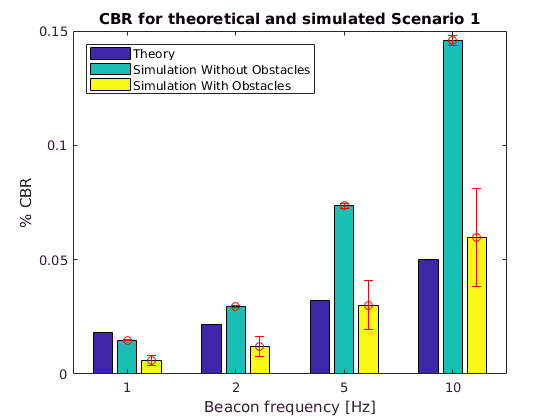


figure (3)
%bar(PDR_MEAN,'DisplayName','PDR_MEAN')
bar(Sc1_c','DisplayName','CBR_MEAN');
hold on

title('CBR for theoretical and simulated Scenario 10');
xlabel('Beacon frequency [Hz]');
ylabel('% CBR');

errorbar(x,CBR_MEAN(1,:),CBR_STD(1,:),'ro');

hold on 
errorbar(x2,CBR2_MEAN(1,:),CBR2_STD(1,:),'ro');
legend('Theory','Simulation Without Obstacles','Simulation With Obstacles','Location','NorthWest');

%ylim([0, 1.1])
xticklabels([1 2 5 10])
hold off

## Resultados de simulación para diferentes reglas


% OS- OnStreet
%Promedio PDR:
PDR_OS = [[0.40681471053708823], [0.4032331986336438], [0.39440935152495926], [0.3767873143334195]];
%Promedio CBR:
CBR_OS =[[0.005986331509146898], [0.011947814613096385], [0.029427580063394042], [0.05753579120291917]];

%STD PDR:
STD_PDR_OS = [[0.0014750657471692382], [0.0040055276615099935], [0.005110585887975328], [0.006320200243836924]];

%STD CBR:
STD_CBR_OS = [[0.0021758722245777], [0.004308496237058689], [0.0105215924625247], [0.020280005958721373]];

NAR_OS = 1-(1-PDR_OS).^5.4579;

STD_NAR_OS = 1-(1-STD_PDR_OS).^5.4579;


% MP - MovinPed

%Promedio PDR:
PDR_MP = [[0.3990678583633519], [0.3949718529523576], [0.385095968129186], [0.3739662738575666]];
%Promedio CBR:
CBR_MP = [[0.005722103290144922], [0.011282359686364889], [0.027348491610065917], [0.05388727905852794]];
%STD PDR:
STD_PDR_MP = [[0.0022208738278831604], [0.003209642579977184], [0.0058627334449584], [0.007133450144343444]];
%STD CBR:
STD_CBR_MP = [[0.002048426853533392], [0.003998177916736177], [0.009515707066208853], [0.01856944888286306]];

NAR_MP = 1-(1-PDR_MP).^5.4579;
STD_NAR_MP = 1-(1-STD_PDR_MP).^5.4579;

% Multiple TX

%Promedio PDR:
PDR_MTX = [0.3860273417346675];
%Promedio CBR:
CBR_MTX = [0.020034934155854167];
%STD PDR:
STD_PDR_MTX = [0.004838705306553557];
%STD CBR:
STD_CBR_MTX = [0.007753098388170993];

NAR_MTX = 1-(1-PDR_MTX).^5.4579;
STD_NAR_MTX = 1-(1-STD_PDR_MTX).^5.4579;


Scr_PDR = [PDR2_MEAN(1,:) ; PDR_OS ; PDR_MP];

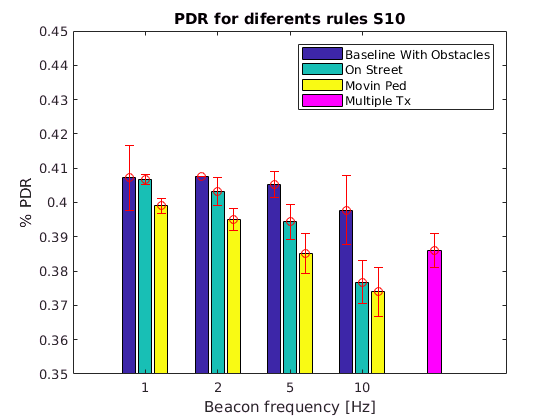

figure (4)

bar(Scr_PDR','DisplayName','PDR_MEAN');
hold on

title('PDR for diferents rules S10');
xlabel('Beacon frequency [Hz]');
ylabel('% PDR');

x=[1 2 3 4];
x1 = x - 0.22;
x3 = x + 0.22;
errorbar(x1,PDR2_MEAN(1,:),PDR2_STD(1,:),'ro');
hold on
errorbar(x,PDR_OS,STD_PDR_OS,'ro');
hold on
errorbar(x3,PDR_MP,STD_PDR_MP,'ro');
legend('Baseline With Obstacles','On Street','Movin Ped','Location','NorthEast');
ylim([0.35,0.45])
xticklabels([1 2 5 10])
hold on 
bar([0 0 0 0 PDR_MTX],0.2,'m','DisplayName','Multiple Tx');
%legend('Baseline With Obstacles','On Street','Movin Ped','Multiple Tx','Location','NorthEast');
hold on
errorbar([-1 -1 -1 -1 PDR_MTX],[0 0 0 0 STD_PDR_MTX],'ro','HandleVisibility','off');
hold off

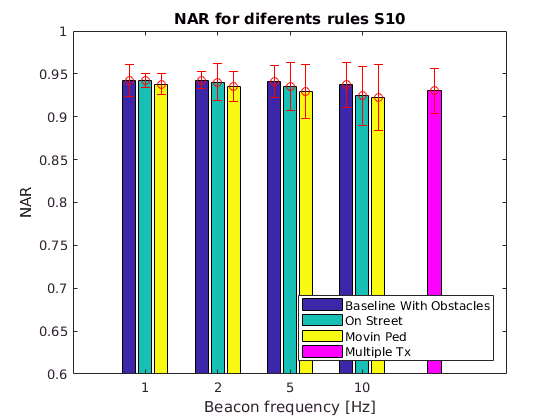

figure (5)

Scr_NAR = [Sc1_nar(3,:) ; NAR_OS ; NAR_MP];
bar(Scr_NAR','DisplayName','NAR_MEAN');
hold on

title('NAR for diferents rules S10');
xlabel('Beacon frequency [Hz]');
ylabel('NAR');

x=[1 2 3 4];
x1 = x - 0.22;
x3 = x + 0.22;
errorbar(x1,(1-(1-PDR2_MEAN(1,:)).^z),(1-(1-PDR2_STD(1,:)).^z),'ro');
hold on
errorbar(x,NAR_OS,STD_NAR_OS,'ro');
hold on
errorbar(x3,NAR_MP,STD_NAR_MP,'ro');
legend('Baseline With Obstacles','On Street','Movin Ped','Location','SouthEast');
ylim([0.6 1]) %.35,0.45])
xticklabels([1 2 5 10])
hold on 
%x4 = [1 2 3 4 5]
bar([0 0 0 0 NAR_MTX],0.2,'m','DisplayName','Multiple Tx');
%legend('Baseline With Obstacles','On Street','Movin Ped','Multiple Tx','Location','NorthEast');
hold on
errorbar([-1 -1 -1 -1 NAR_MTX],[0 0 0 0 STD_NAR_MTX],'ro','HandleVisibility','off');
hold off

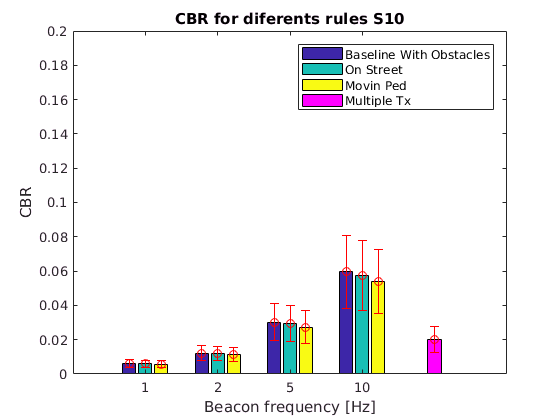

figure (6)
Scr_CBR = [CBR2_MEAN(1,:) ; CBR_OS ; CBR_MP];

bar(Scr_CBR','DisplayName','CBR_MEAN');
hold on

title('CBR for diferents rules S10');
xlabel('Beacon frequency [Hz]');
ylabel('CBR');

x=[1 2 3 4];
x1 = x - 0.22;
x3 = x + 0.22;
errorbar(x1,CBR2_MEAN(1,:),CBR2_STD(1,:),'ro');
hold on
errorbar(x,CBR_OS,STD_CBR_OS,'ro');
hold on
errorbar(x3,CBR_MP,STD_CBR_MP,'ro');
legend('Baseline With Obstacles','On Street','Movin Ped','Location','NorthEast');
ylim([0 0.2]) %.35,0.45])
xticklabels([1 2 5 10])
hold on 
bar([0 0 0 0 CBR_MTX],0.2,'m','DisplayName','Multiple Tx');
%legend('Baseline With Obstacles','On Street','Movin Ped','Multiple Tx','Location','NorthEast');
hold on
errorbar([-1 -1 -1 -1 CBR_MTX],[0 0 0 0 STD_CBR_MTX],'ro','HandleVisibility','off');
hold off